# open Run over all WDs

### Load WD catalogs

RAD = 180 / pi;
PWD = pwd;

cd(['~/marvin/catsHTM/WD/WDEDR3/'])


 WDS  = catsHTM.cone_search('WDEDR3',50./RAD, 45./RAD, 3600*5156.6201561774, 'OutType','AstroCatalog');
                

if ~isempty(WDS.Table)

    AllWds = size(WDS.Table,1);

    visWds = WDS.Table{:,11} < 19.6 ;
    visWds = visWds & WDS.Table{:,7} > 0;
     visWds = visWds & WDS.Table{:,2} > -15./RAD;

    fprintf('\nOut of %i WDs %i are below Gmag 19.6 \n',AllWds,sum(visWds))

     wd= WDS.Table(visWds,:);
     ra  = WDS.Table{visWds,1}*RAD;
     dec = WDS.Table{visWds,2}*RAD;

end


Out of 1280266 WDs 105501 are below Gmag 19.6 



cd(PWD)



Identifiers = {};
AbsMags = zeros(height(wd),1);
NonSingleStar = zeros(height(wd),1);
Dist = zeros(height(wd),1);
Plx = zeros(height(wd),1);
PWD = pwd;
h = waitbar(0);
Nwd = height(wd);
Neighbors = zeros(Nwd,1);
for Jwd = 1 : height(wd)


        cd('~/marvin/catalogs/GAIA/DR3/')
        AC=catsHTM.cone_search('GAIADR3',ra(Jwd)./RAD, dec(Jwd)./RAD, 3,'OutType','AstroCatalog');
        
        if size(AC.Table,1) == 1
            NoneSingleStar(Jwd) = AC.Table.non_single_star;
            AbsMags(Jwd) = AC.Table.phot_bp_mean_mag - (5.*log10(1000./AC.Table.Plx)-5);
            Plx(Jwd) = AC.Table.Plx;
            Dist(Jwd) = 1000./AC.Table.Plx;

        elseif size(AC.Table,1) > 1

            NoneSingleStar(Jwd) = AC.Table.non_single_star(1);
            AbsMags(Jwd) = AC.Table.phot_bp_mean_mag(1) - (5.*log10(1000./AC.Table.Plx(1))-5);
            Plx(Jwd) = AC.Table.Plx(1);
            Dist(Jwd) = 1000./AC.Table.Plx(1);
            Neighbors(Jwd) = size(AC.Table,1) -1 ;

        else
            NoneSingleStar(Jwd) = -1;
            AbsMags(Jwd) = -1;
            Plx(Jwd) = -1;
            Dist(Jwd) = -1;


        end
            


        queryURL = sprintf('http://simbad.u-strasbg.fr/simbad/sim-coo?Coord=%f+%f&Radius=%f&Radius.unit=arcsec&output.format=ASCII', ra(Jwd), dec(Jwd), 4);
        response = webread(queryURL);

        if ~isa(response,'uint8')


            startIdx = strfind(response, 'Identifiers (');
            if ~isempty(startIdx)
                idSection = extractAfter(response, 'Identifiers (');
    
                % Extract the first identifier (assuming it's after "Identifiers (")
                firstColonIdx = strfind(idSection, ':');
                if ~isempty(firstColonIdx)
                    idText = extractAfter(idSection(firstColonIdx(1):end), ':');
            
                    % Stop at the first occurrence of a number followed by a space
                    firstIdentifier = regexp(idText, '[A-Za-z0-9.]+ [A-Za-z0-9.+-]+', 'match', 'once');
    
    
                else
                    firstIdentifier = 'None';
                end
                % Extract the Gaia designation number (e.g., Gaia DR3)
                gaiaID = regexp(idSection, 'Gaia DR3 \S+', 'match', 'once');
                if isempty(gaiaID)
                    gaiaID = regexp(idSection, 'Gaia DR2 \S+', 'match', 'once');
    
                end
    
                if isempty(gaiaID)
                    gaiaID = 'None'
                end
    
                disp(['First Identifier: ', firstIdentifier]);
                disp(['Gaia Designation: ', gaiaID]);
            else
                disp('No identifiers found.');
                gaiaID = 'None';
                firstIdentifier = 'None';
            end

        else
               gaiaID = 'None';
               firstIdentifier = 'None';

        end

        Identifiers{end +1} = {firstIdentifier gaiaID};

        waitbar(Jwd/Nwd,h,sprintf('%i / %i WDs scanned',Jwd,Nwd))


     
    
                                                
end

First Identifier: GALEX J000116.5+000204


Gaia Designation: Gaia DR3 2546038264968976768


First Identifier: GALEX J000104.0+000356


Gaia Designation: Gaia DR3 2546033488965366784


First Identifier: GALEX J000127.4+003800


Gaia Designation: Gaia DR3 2738250352251363968


First Identifier: GALEX J000557.2+001833


Gaia Designation: Gaia DR3 2546096749538393600


First Identifier: GALEX J000630.5+002324


Gaia Designation: Gaia DR3 2546098257071794560


First Identifier: GALEX J000738.0+004004


Gaia Designation: Gaia DR3 2546133720617955072


First Identifier: SDSS J000622.62+010958.7


Gaia Designation: Gaia DR3 2546593965017189888


First Identifier: GALEX J000619.0+011145


Gaia Designation: Gaia DR3 2546597194832599808


First Identifier: GALEX J000042.8+013222


Gaia Designation: Gaia DR3 2738626591386423424


First Identifier: GALEX J000509.9+003810


Gaia Designation: Gaia DR3 2546165258562066816


First Identifier: GALEX J000429.0+005801


Gaia Designation: Gaia DR3 2738365182496839040


First Identifier: GALEX J002040.0+001106


Gaia Designation: Gaia DR3 2545305410405677312


First Identifier: GALEX J001836.1+003152


Gaia Designation: Gaia DR3 2545567334691271424


First Identifier: GALEX J001742.4+004138


Gaia Designation: Gaia DR3 2545579360599665792


First Identifier: GALEX J001730.6+004225


Gaia Designation: Gaia DR3 2545580284015975424


First Identifier: GALEX J001715.8+011311


Gaia Designation: Gaia DR3 2547161106858695680


No identifiers found.
No identifiers found.


First Identifier: GALEX J001306.2+005507


Gaia Designation: Gaia DR3 2546387153752124160


First Identifier: GALEX J001529.7+010522


Gaia Designation: Gaia DR3 2546405570572258944


First Identifier: Gaia DR3


Gaia Designation: Gaia DR3 2546432646046169088


First Identifier: GALEX J000246.9+042859


Gaia Designation: Gaia DR3 2741868265198803200


First Identifier: GALEX J000024.2+052433


Gaia Designation: Gaia DR3 2745002934193618816


First Identifier: GALEX J000515.1+025150


Gaia Designation: Gaia DR3 2739206274531999744


First Identifier: Gaia DR3


Gaia Designation: Gaia DR3 2739946486376214528


First Identifier: Gaia DR3


Gaia Designation: Gaia DR3 2740514903824114944


First Identifier: Gaia DR3


Gaia Designation: Gaia DR3 2739231150982741760


First Identifier: GALEX J000742.8+030907


Gaia Designation: Gaia DR3 2740739509137207936


First Identifier: Gaia DR3


Gaia Designation: Gaia DR3 2739292311317118336


First Identifier: GALEX J000631.9+033110


Gaia Designation: Gaia DR3 2740810771234677376


First Identifier: GALEX J000625.6+034108


Gaia Designation: Gaia DR3 2740818192938196608


First Identifier: GALEX J000543.1+040312


Gaia Designation: Gaia DR3 2741599395949650944


First Identifier: GALEX J000314.2+033550


Gaia Designation: Gaia DR3 2740076263107766528


First Identifier: Gaia DR3


Gaia Designation: Gaia DR3 2741567445689272192


First Identifier: GALEX J000403.9+034256


Gaia Designation: Gaia DR3 2740084715603437440


First Identifier: GALEX J000423.5+040203


Gaia Designation: Gaia DR3 2741640352757843072


First Identifier: GALEX J001041.2+010044


Gaia Designation: Gaia DR3 2546354202763540992


First Identifier: SDSS J000707.62+011430.4


Gaia Designation: Gaia DR3 2546601116138975232


First Identifier: Gaia DR3


Gaia Designation: Gaia DR3 2546611316685377408


Error using webread (line 122)
Error downloading content from InterruptException(ctrl-c). Your network connection may be down or your proxy settings improperly configured.

cd(PWD)

Nwd = height(wd)

Nwd =       105501






% > 1616 > 1925 > 1959 > 6445> 7237 > 8122 > 8298 > 8600 > 9707
% [1:9951] WD with 3 visits

% problems with 22561 - 24000 
% did 24000 - 27669
% next is 30755

Counts =76700;  
Count  = 76700;

h = waitbar(0)

h =   Figure (TMWWaitbar) with properties:

      Number: []
        Name: ''
       Color: [1 1 1]
    Position: [581.25 345.75 277.5 78.75]
       Units: 'points'

  Show all properties


Ind is empty for all elements.
Ind is empty for all elements.
Ind is empty for all elements.
Ind is empty for all elements.
Ind is empty for all elements.
Ind is empty for all elements.
Ind is empty for all elements.
Ind is empty for all elements.
Ind is empty for all elements.
Ind is empty for all elements.
Ind is empty for all elements.
Ind is empty for all elements.
Ind is empty for all elements.
Ind is empty for all elements.
Ind is empty for all elements.
Ind is empty for all elements.
Ind is empty for all elements.
Ind is empty for all elements.
Ind is empty for all elements.
Ind is empty for all elements.
Ind is empty for all elements.
Ind is empty for all elements.
Ind is empty for all elements.
Ind is empty for all elements.
Ind is empty for all elements.
Ind is empty for all elements.
Ind is empty for all elements.
Ind is empty for all elements.
Ind is empty for all elements.
Ind is empty for all elements.
Ind is empty for all elements.
Ind is empty for all elements.
Ind is e

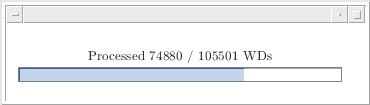

Index exceeds the number of array elements. Index must not exceed 36.

Error in cleanMatchedSources1 (line 25)
    if mean(abs(jd - limMagt(1:length(jd)))) > 20 / (24 * 60)

Error in WDRun3>detectInMS (line 264)
                    [mms,nanIdx] =  cleanMatchedSources1(batch{Ibatch}, args);

Error in 


for Iwd = Counts : Nwd

    
    getData(ra(Count),dec(Count), Count,wd(Count,:),'minVis',10,"outputDir",'/home/yarinms/Projects/WD_survey/WDRun_General_N0009',"Name",sprintf("WD N%i",Count))
    Count = Count +1;
    waitbar(Iwd/Nwd,h,sprintf("Processed %i / %i WDs",Iwd,Nwd))





end




 getData(RA,Dec,Args)

### Conduct a search in marvin

Minimum number of visits should be more than 15 (i think)

script for WD1856+534

% Open the SQLite database connection
dbConn = sqlite('LAST_WDs20.db', 'connect');
 % Query to handle NULL values and exclude BLOB columns
querySQL = ['SELECT WD_Name, RA, Dec, COALESCE(P_wd, 0) AS P_wd, COALESCE(BPmag, 0) AS BPmag, ', ...
            'COALESCE(Gmag, 0) AS Gmag, COALESCE(Plx, 0) AS Plx, COALESCE(Abs_Mag, 0) AS Abs_Mag, ', ...
            'Date, Telescope, COALESCE(FieldID, "") AS FieldID, COALESCE(CropID, 0) AS CropID, ', ...
            'COALESCE(LimMag, 0) AS LimMag, COALESCE(FWHM, 0) AS FWHM, COALESCE(Airmass, 0) AS Airmass, ', ...
            'COALESCE(VisitID, "") AS VisitID, COALESCE(LC_Quality, "") AS LC_Quality, ', ...
            'COALESCE(meanX, 0) AS meanX, COALESCE(meanY, 0) AS meanY, COALESCE(SimbadLink, "") AS SimbadLink, ', ...
            'COALESCE(ImageLink, "") AS ImageLink, COALESCE(NanCount, 0) AS NanCount, ', ...
            'COALESCE(ConsecutiveNans, 0) AS ConsecutiveNans, COALESCE(NptsDet1_flux, 0) AS NptsDet1_flux, ', ...
            'COALESCE(NptsDet2_flux, 0) AS NptsDet2_flux, COALESCE(BadFlagCount, 0) AS BadFlagCount, ', ...
            'COALESCE(NonBadFlagCount, 0) AS NonBadFlagCount, COALESCE(controlSD, 0) AS controlSD, ', ...
            'COALESCE(fluxSD, 0) AS fluxSD, COALESCE(magSD, 0) AS magSD, COALESCE(DetectionCount, 0) AS DetectionCount, ', ...
            'COALESCE(QualityFlag, "") AS QualityFlag, COALESCE(LAST_ID, "") AS LAST_ID, ', ...
            'COALESCE(designation_id, "") AS designation_id, COALESCE(Year, 0) AS Year, COALESCE(Month, 0) AS Month, ', ...
            'COALESCE(Day, 0) AS Day, COALESCE(Mount, 0) AS Mount, COALESCE(Camera, 0) AS Camera, ', ...
            'COALESCE(Detection, 0) AS Detection, COALESCE(SN_3, 0) AS SN_3, COALESCE(SN_2, 0) AS SN_2, ', ...
            'COALESCE(Nvisits, 0) AS Nvisits, COALESCE(NvalidPoints, 0) AS NvalidPoints, ', ...
            'COALESCE(SDNoEvent, 0) AS SD_no_event, COALESCE(MedNoEvent, 0) AS Med_no_event, ', ...
            'COALESCE(EventDepth, 0) AS Event_Depth, COALESCE(SDNoEvent2, 0) AS SD_no_event2, ', ...
            'COALESCE(MedNoEvent2, 0) AS Med_no_event2, COALESCE(EventDepth2, 0) AS Event_Depth2, ', ...
            'COALESCE(SDNoEvent2Flux, 0) AS SD_no_event2_flux, COALESCE(MedNoEvent2Flux, 0) AS Med_no_event2_flux, ', ...
            'COALESCE(EventDepth2flux, 0) AS Event_Depth2_flux, COALESCE(SDNoEvent1Flux, 0) AS SD_no_event1_flux, ', ...
            'COALESCE(MedNoEvent1Flux, 0) AS Med_no_event1_flux, COALESCE(EventDepth1flux, 0) AS Event_Depth1_flux, ', ...
            'COALESCE(Identifier, "") AS Identifier FROM LightCurveData;'];

% Fetch results
results3 = fetch(dbConn, querySQL)

results3 = 24880×57 table
               WD_Name                  RA       Dec       P_wd      BPmag      Gmag      Plx     Abs_Mag            Date                Telescope         FieldID      CropID    LimMag     FWHM     Airmass    VisitID    LC_Quality    meanX     meanY                                                             SimbadLink                                                             ImageLink    NanCount    ConsecutiveNans    NptsDet1_flux    NptsDet2_flux    BadFlagCount    NonBadFlagCount    controlSD

### Handle visit grouping

find unique nights with more than mnVisits of the field per night.

- For every path with more than minVisitis we group MS objects of consecutive vivsits intra-night   

getData(RA,Dec);

Unrecognized function or variable 'RA'.

# Functions

# Functions

Merge - get lim mag - get lc - detect

   % get groupedMS
   % you neeed Table check its crop id fits to list id
   function detectInMS(groupedMS,Table,outputDir,WDtable)
    cx = 0;

           args = struct(...
            'MagField', {{'MAG_PSF'}}, ...
            'MagErrField', {{'MAGERR_PSF'}}, ...
            'BadFlags', {{'Saturated', 'Negative', 'NaN', 'Spike', 'Hole', 'NearEdge'}}, ...
            'EdgeFlags', {{'Overlap'}}, ...
            'runMeanFilterArgs', {{'Threshold', 5, 'StdFun', 'OutWin'}}, ...
            'Nvisits', 2, ...
            'Ndet', 16*2 ...
        );
           lcData  = cell(0);
           batch = groupedMS;
    

    for Ibatch = 1 : length(batch)

                    
                        % Look for source in batch:
                        Src = batch{Ibatch}.coneSearch(Table.RA,Table.Dec);
                        IndValues = {Src.Ind};

                        % Check for non-empty 'Ind' values
                        firstNonEmptyInd = find(cellfun(@(x) ~isempty(x), IndValues), 1);

                        % Analyze the result
                        if ~isempty(firstNonEmptyInd)
                            args.mergeBy = firstNonEmptyInd;
                        else
                           
                            disp('Ind is empty for all elements.');
                            continue;
                        end
                        
                        catJD = [];
                        LimMag = [];
                        FWHM   = [];
                        AM = [];

                        for Ivis = 1 : numel(batch{Ibatch})

                            %OP        = WDtransits2.EfficientReadFromCat(batch{Ibatch}(Ivis).FileName, Table.CropID);
                            %obsParams = {obsParams; {OP}};
                            try
                                OP = WDtransits3.EfficientReadFromCat(batch{Ibatch}(Ivis).FileName, Table.CropID);
                                LimMag  =  [LimMag; OP.LimMag];
                                catJD   =  [catJD; OP.JD];
                                FWHM    =  [FWHM; OP.FWHM];
                                am      =  getAirmass(OP);
                                AM      =  [AM ; am];
                            catch
                                % If an error occurs (e.g., FileName does not exist), set OP to []
                                OP = [];
                                LimMag    =  [LimMag; 20*ones(length(batch{Ibatch}.JD),1)];
                                catJD    =  [catJD; batch{Ibatch}.JD];
                                disp(['Warning: File not found or another error occurred for ', batch{Ibatch}(Ivis).FileName]);
                            end

                            



                            
                        end

                    args.catJD =catJD ; args.LimMag = LimMag;

                    

                    [mms,nanIdx] =  cleanMatchedSources1(batch{Ibatch}, args);
                    lcData{Ibatch}.limMag = LimMag;
                    lcData{Ibatch}.catJD = catJD;
                    %mms.coneSearch(Table.RA,Table.Dec).Ind
                    lcData{Ibatch} = WDtransits3.extractLightCurve(lcData{Ibatch}, mms,  Table.RA,Table.Dec,args);
                    
                    %lcData{Ibatch} = WDtransits3.handleNaNValues(lcData{Ibatch},mms, mms.Nepoch);
                    [~,fname,~] = fileparts(batch{Ibatch}(Ivis).FileName);
                    part = strsplit(fname,'_');
                    lcData{Ibatch}.Tel = part{1};
                    lcData{Ibatch}.Date = part{2};
                    lcData{Ibatch}.Table.FWHM = FWHM;
                    lcData{Ibatch}.Table.Airmass = AM;
                    lcData{Ibatch}.Table.visTable = Table;
                    lcData{Ibatch}.Table.FieldID  = Table.FieldID;
                    lcData{Ibatch}.Table.fwhm    = median(FWHM,'omitnan');
                    lcData{Ibatch}.Table.airmass = median(AM,'omitnan');
                    lcData{Ibatch}.Table.RA = Table.RA;
                    lcData{Ibatch}.Table.Dec = Table.Dec;
                    lcData{Ibatch}.Table.Gmag = WDtable.Gmag;
                    lcData{Ibatch}.Table.BPmag = WDtable.BPmag;
                    lcData{Ibatch}.Table.BpRp = WDtable.BPmag - WDtable.RPmag;
                    lcData{Ibatch}.Table.Pwd = WDtable.Pwd;
                    lcData{Ibatch}.Table.AbsMag= WDtable.Gmag - (5.*log10(1000./WDtable.Plx)-5);
                    lcData{Ibatch}.Table.Total_Visits = Table.Nvisits;
                    lcData{Ibatch}.Table.Visits_Found= length(batch) ;
                    lcData{Ibatch}.Table.Subframe = Table.CropID;
                    lcData{Ibatch}.Table.Name = Table.Name;
                    


                   % NO TABLE FOR NOW lcData{Iwd,Ibatch}.Table = table(Iwd,:);



                     % if sum lcData{Iwd,Ibatch}.nanIndinces > 1
                     % find pattern in more source in mms



%                    lcData{Iwd,Ibatch} = transitSearch.handleNaNValues(lcData, numel(catJD));
         
                  if isfield(lcData{Ibatch},'Res')
                      % find how many detections you had of this target TBD
                      % in the future
                        a = 1;

                  else
                        %Nnans =  sum(nanIdx);
                        lcData{Ibatch}.nanIndices = nanIdx(:,lcData{Ibatch}.Ind);
                        results{Ibatch}  = WDtransits3.detectTransits(lcData{Ibatch}, args);
                        res.detection1 = results{Ibatch}.detection1;
                        res.detection1flux = results{Ibatch}.detection1flux;
                        res.detection2 = results{Ibatch}.detection2;
                        res.detection2flux = results{Ibatch}.detection2flux;

                        [AbsMag, Plx, Dist, NonSingleStar, Neighbors, Identifiers] = getWDParams(Table.RA, Table.Dec);
                        if isnan(AbsMag) || ~isreal(AbsMag)
                            AbsMag = 0;

                        end
                        if isnan(Plx)
                            Plx = 0;
                        end
                        if isnan(NonSingleStar)
                            NonSingleStar=0;
                        end
                        if isnan(Neighbors)
                            Neighbors=0;
                        end

                        % Populate lcData with these parameters
                        lcData{Ibatch}.Table.WDtable = WDtable;
                        lcData{Ibatch}.Table.AbsMag = AbsMag;
                        lcData{Ibatch}.Table.Plx = Plx;
                        lcData{Ibatch}.Table.Dist = Dist;
                        lcData{Ibatch}.Table.NonSingleStar = NonSingleStar;
                        lcData{Ibatch}.Table.Neighbors = Neighbors;
                        lcData{Ibatch}.VisitID = sprintf('# %i/%i',Ibatch,length(batch));
                        
                        matches = regexp(Identifiers{2},'Gaia DR3 (\d+)', 'tokens');
                        if ~isempty(matches)
                            designation_id = matches{1}{1}; 
                        else
                            designation_id = '';
                        end
                        lcData{Ibatch}.Table.designation_id = designation_id;
                     
                        if length(Identifiers{2}) > 4 && length(Identifiers{1}) > 4
                        
                                if sum(Identifiers{1}(1:8) == Identifiers{2}(1:8)) == 8
                                    lcData{Ibatch}.Table.Identifiers.Gaia = Identifiers{2};
                                    lcData{Ibatch}.Table.Identifiers.First = Identifiers{2};
                                else
                                    lcData{Ibatch}.Table.Identifiers.First = Identifiers{1};
                                    lcData{Ibatch}.Table.Identifiers.Gaia = Identifiers{2};
                                end

                        else
                            lcData{Ibatch}.Table.Identifiers.First = Identifiers{1};
                            lcData{Ibatch}.Table.Identifiers.Gaia = Identifiers{2};


                        end
                       if ~isempty(res.detection1.events) || ~isempty(res.detection2.events)
                                                a = 2;
                       end
                        lcData{Ibatch}.Table.SimbadLink = sprintf('http://simbad.u-strasbg.fr/simbad/sim-coo?Coord=%f+%f&Radius=%f&Radius.unit=arcsec&output.format=ASCII', Table.Dec, Table.RA, 4);
                        res.detection1.lcStdWithoutEvent1 =0;
                            res.detection1.lcMedWithoutEvent1 = 0;
                            res.detection1.EventDepth1 =  0;
                             res.detection2.lcStdWithoutEvent2 =0;
                            res.detection2.lcMedWithoutEvent2 = 0;
                            %depth = 
                            res.detection2.EventDepth2 = 0;
                              res.detection1flux.lcStdWithoutEvent1flux =0;
                            res.detection1flux.lcMedWithoutEvent1flux = 0;
                            %depth = 
                            res.detection1flux.EventDepth1flux = 0;
                            
                            res.detection2flux.lcStdWithoutEvent2flux = 0;
                            res.detection2flux.lcMedWithoutEvent2flux = 0;
                            %depth = 
                            res.detection2flux.EventDepth2flux =  0;

                        %% try to create here beacuse cannot create in insert
                        mask = true(size(lcData{Ibatch}.lc));
                        if ~isempty(res.detection1.events)
                            mask1 = mask;
                            mask1(res.detection1.events) = false;
                            
                            lcWithoutEvent1 = lcData{Ibatch}.lc(mask1);
                    
                    
                            res.detection1.lcStdWithoutEvent1 = std(lcWithoutEvent1,'omitnan');
                            res.detection1.lcMedWithoutEvent1 = median(lcWithoutEvent1,'omitnan');
                  
                            res.detection1.EventDepth1 =  max(lcData{Ibatch}.lc(~mask1)) - res.detection1.lcMedWithoutEvent1;
                            
                        end
                        mask2 = true(size(lcData{Ibatch}.lc));
                        
                        if ~isempty(res.detection2.events)
                           
                            mask = mask2;
                            mask(res.detection2.events) = false;
                          
                            lcWithoutEvent2 = lcData{Ibatch}.lc(mask);
                    
                    
                            res.detection2.lcStdWithoutEvent2 = std(lcWithoutEvent2,'omitnan');
                            res.detection2.lcMedWithoutEvent2 = median(lcWithoutEvent2,'omitnan');
                            %depth = 
                            res.detection2.EventDepth2 =  max(lcData{Ibatch}.lc(~mask)) - res.detection2.lcMedWithoutEvent2;
                            
                        end
                        mask3 = true(size(lcData{Ibatch}.lc));
                        if ~isempty(res.detection1flux.events)
                                  
                            mask = mask3;
                            mask(res.detection1flux.events) = false;
                          
                            lcWithoutEvent1flux = lcData{Ibatch}.relFlux(mask);
                    
                    
                            res.detection1flux.lcStdWithoutEvent1flux = std(lcWithoutEvent1flux,'omitnan');
                            res.detection1flux.lcMedWithoutEvent1flux = median(lcWithoutEvent1flux,'omitnan');
                            %depth = 
                            res.detection1flux.EventDepth1flux =  min(lcData{Ibatch}.relFlux(~mask)) - res.detection1flux.lcMedWithoutEvent1flux;
                            
                        
                        end
                        mask4 = true(size(lcData{Ibatch}.lc));
                        if ~isempty(res.detection2flux.events)
                            
                            mask = mask4;
                            mask(res.detection2flux.events) = false;
                          
                            lcWithoutEvent2flux = lcData{Ibatch}.relFlux(mask);
                    
                    
                            res.detection2flux.lcStdWithoutEvent2flux = std(lcWithoutEvent2flux,'omitnan');
                            res.detection2flux.lcMedWithoutEvent2flux = median(lcWithoutEvent2flux,'omitnan');
                            %depth = 
                            res.detection2flux.EventDepth2flux =  min(lcData{Ibatch}.relFlux(~mask)) - res.detection2flux.lcMedWithoutEvent2flux;

                        
                        
                        
                        end


                        insertLCDataToDB6(lcData{Ibatch}, res, 'LAST_WDs20.db') % outputDir = '/Users/yarinms/Documents/Data/6thRun';
                      
                        WDtransits3.plotDetectionResults(results, 1, Ibatch, args, true, outputDir)
                
                        a = 2; 
                  end

                   


                         
    
    
    end

   end


Group MS

function groupedMS = groupedMS(MSvisits, Nvisits)
    % Get the total number of visits
    totalVisits = numel(MSvisits);
    
    % Calculate the number of full groups and the remainder
    numGroups = floor(totalVisits / Nvisits);
    remainder = mod(totalVisits, Nvisits);
    
    % Preallocate the groupedMS cell array
    groupedMS = cell(1, numGroups + (remainder > 0));
    
    % Loop through and group the visits
    for i = 1:numGroups
        startIdx = (i-1) * Nvisits + 1;
        endIdx = i * Nvisits;
        groupedMS{i} = MSvisits(startIdx:endIdx);
    end
    
    % Handle the remainder if there is one
    if remainder > 0
        startIdx = numGroups * Nvisits + 1;
        groupedMS{end} = MSvisits(startIdx:end);
    end
end

Make a consecutive search 

    function AllConsecutive = consecutiveSearch(List,Args)

            arguments
                List
                Args.MaxTimeBetweenVisits = (20*40)./(86400);

            end
    
             % sort List by time
            AllJD  = [List.MinJD].';
            [~,Is] = sort(AllJD);
            Args.List = List(Is);

            AllFields = {List.FieldID}; 
            UniqueFields = unique(AllFields);
            Nuf          = numel(UniqueFields);
            K = 0;
            for Iuf=1:1:Nuf
                % for each unique field
                % search all appearances
                FlagF = strcmp(UniqueFields{Iuf}, AllFields);
                IndF  = find(FlagF);

                ListF = List(IndF);

                DiffTime = [diff(AllJD(IndF)); mean(diff(AllJD(IndF)))];
                FlagConsecutive = abs(DiffTime) < Args.MaxTimeBetweenVisits;

                [ListConsecutive] = tools.find.findListsOfConsecutiveTrue(FlagConsecutive);
                Ncons = numel(ListConsecutive);
                for Icons=1:1:Ncons
                    K = K + 1;
                    AllConsecutive{K,1} = ListF(ListConsecutive{Icons});
                end

                if ~exist('AllConsecutive','var')

                    AllConsecutive = {};

                end
            end

    end

make a list for consecutive search

    function List = prepListOfConVisits(path,Table,args)

            arguments
                path
                Table
                args.fileTemplate
                args.CropID
            end
            Ind = 0;
            PWD = pwd;
            cd(path) % This must be a path to proc directory

            DirVisit = io.files.dirDir();
            Nv = numel(DirVisit);
            for Iv=1:1:Nv
                %[Iy, Im, Id, Iv, Ind]
                cd(DirVisit(Iv).name);
                
                Files = dir(args.fileTemplate);
                FN = FileNames.generateFromFileName({Files.name});
                if FN.nfiles>0
                    Ind = Ind + 1;
                    CropID = FN.CropID;
                    JD     = FN.julday;
                    List(Ind).FieldID = FN.FieldID{1};
                 
                    List(Ind).VistDir = DirVisit(Iv).name;
                    List(Ind).Year    = Table.Year;
                    List(Ind).Month   = Table.Month;
                    List(Ind).Day     = Table.Day;
        
                    List(Ind).Path    = fullfile(path, DirVisit(Iv).name,'','');
                    
                    List(Ind).AllFiles = {Files.name};
                    List(Ind).CropID   = CropID;
                    List(Ind).JD       = JD;
                    List(Ind).MinJD    = min(JD);
                end
                cd ..
            end
            cd(PWD)

    end

Group visits from path to consecutive Nvisit MS objects

function AllConsecutive = mergeConsecutiveVisits(path,Table,args)
    arguments
        path 
        Table
        args.MaxTimeBetweenVisits = (20*40)./(86400);
    end
    
     Temp = compose("*%s_000_001_%03i_sci_merged_MergedMat_1.hdf5", Table.FieldID,Table.CropID);



  
     List           = prepListOfConVisits(path,Table,"fileTemplate",Temp);
     AllConsecutive = consecutiveSearch(List);
     secondDimensions = cellfun(@(x) size(x, 2), AllConsecutive);
    % AllConsecutive = AllConsecutive{:};
   
   % fprintf('\n%i consecutive groups in dir: \n %s\n',height(AllConsecutive),path)
   % fprintf('\n%i consecutive visits \n',secondDimensions)
    
   



end

function MSvisits = consecutiveMS(AllConsecutive,args)

    FileName = [] ;
    Folder   = [] ;

    for Icon = 1 : size(AllConsecutive,2)

        Folder   = [ Folder; string(AllConsecutive(Icon).Path)];
        FileName = [FileName; string(AllConsecutive(Icon).AllFiles(1))];

    end
    list.Folder   = Folder;
    list.FileName = FileName ; 
    list.CropID   = AllConsecutive(1).CropID;

    MSvisits      =  MatchedSources.readList(list);


end

Find unique directories with minimal number of visits of the same field

function [Table,Path] = finduniqueVisits(path,args)

    arguments
        path
        args.minVis = 4;

    end


    [U, xxx, iu] = unique(path(:, {'Year','Month','Day','Mount','Camera','CropID','FieldID'}));

    uc = accumarray(iu, 1);
    cond = (uc >= args.minVis); %  18+ visits -> 2+ hrs. ;
    U = U(cond, :);
    uc = uc(cond);

    if ~isempty(U)
        U.Nvisits = uc;
        Table = U;
        Path = compose("~/marvin/LAST.01.%02i.%02i/%i/%02i/%02i/proc/", U.Mount, U.Camera, U.Year, U.Month, U.Day);
        Path = char(Path);    

    else
         uc = accumarray(iu, 1);
         Table = [];Path = [];
        %assert(~isempty(U),sprintf('\nCould not find more than %i consecutive visits for the provided path.\nCheck for a new LASTFields object.',max(uc)))
    end
      

end

Get Visit directories for a target within LAST AllFields object

    function Paths = getcoordPaths(RA,Dec,args)
        % Must initilize the path for the LAST visits catalog
        OT = load('/home/yarinms/marvin/LAST_Visits_20240810.mat');
        OT = OT.OT;
 
        Flag = celestial.coo.findInBox(RA, Dec, [OT.RAU1, OT.RAU2, OT.RAU3, OT.RAU4], [OT.DECU1, OT.DECU2, OT.DECU3, OT.DECU4]);

        Paths = OT(Flag,:);

    end

function getData(RA,Dec,Iwd,WDtable,Args)
arguments
    RA
    Dec
    Iwd
    WDtable
    Args.minVis = 10;
    Args.Name = '';
    Args.outputDir = '/Users/yarinms/Documents/Data/7thRun';
end

 if ~exist(Args.outputDir ,'dir')
        mkdir(Args.outputDir);
        mkdir(strcat(Args.outputDir,'/FluxDetections'));
 end

Paths = getcoordPaths(RA,Dec);
Npaths = height(Paths);
%fprintf('\n%i Paths Have been detected for target # %i (%.3f,%.3f)\n',Npaths,Iwd,RA,Dec)
[Table,Path] = finduniqueVisits(Paths,"minVis",Args.minVis );

if ~isempty(Table)
    %fprintf('\n%i Paths Have been detected for target # %i (%.3f,%.3f)\n',Npaths,Iwd,RA,Dec)

        
        Npaths = height(Path);
        
        for Idir = 1 : Npaths
            tab  = Table(Idir,:);
            tab.RA = RA;
            tab.Dec= Dec;
            tab.Name =  Args.Name ;
            path = Path(Idir,:);
            MSpaths = mergeConsecutiveVisits(path,tab);
       if ~isempty(MSpaths)
 
            Ngroups = height(MSpaths);
        
            for Ig = 1 : Ngroups
        
                MSvisit =  consecutiveMS(MSpaths{Ig});
                % analyaze MS visit
                % Group
                Nvisits = 2;
                MSgroup = groupedMS(MSvisit, Nvisits);
                % get lc and detect
              
                detectInMS(MSgroup,tab,   Args.outputDir,WDtable);
        
        
        
            end
       else
           a=1;
       end
        
        end
else
    %fprintf('\n%i Paths Have been detected for target # %i (%.3f,%.3f)\n NO consecutive visits\n',Npaths,Iwd,RA,Dec)

    return
end
end

% Open the SQLite database connection
dbConn = sqlite('LAST_WDs12.db', 'connect');


% Use COALESCE to handle NULL values
querySQL = ['SELECT WD_Name RA, Dec, COALESCE(P_wd, 0) AS P_wd, COALESCE(BPmag, 0) AS BPmag, ', ...
        'COALESCE(Gmag, 0) AS Gmag, COALESCE(Abs_Mag, 0) AS Abs_Mag, ', ...
        'Date, Telescope, COALESCE(FieldID, 0) AS FieldID, COALESCE(CropID, 0) AS CropID, ', ...
        'COALESCE(NptsDet1, 0) AS NptsDet1, COALESCE(NonDetectPts, 0) AS NonDetectPts, ', ...
        'COALESCE(Neighbors, 0) AS Neighbors, COALESCE(Depth, 0) AS Depth, ', ...
        'COALESCE(meanX, 0) AS meanX, COALESCE(meanY, 0) AS meanY FROM LightCurveData;'];

results = fetch(dbConn, querySQL);
disp(results);

      RA         Dec      P_wd    BPmag    Gmag    Abs_Mag            Date                Telescope       FieldID    CropID    NptsDet1    NonDetectPts    Neighbors    Depth      meanX        meanY  
    _______    _______    ____    _____    ____    _______    _____________________    _______________    _______    ______    ________    ____________    _________    _____    _________    _________

    12.3096     6.5103     0        0       0         0

% Close the database connection
close(dbConn);






% Open the SQLite database connection
dbConn = sqlite('LAST_WDs14.db', 'connect');

% Query with COALESCE for all fields to handle NULL values
querySQL = ['SELECT WD_Name, RA, Dec, COALESCE(P_wd, 0) AS P_wd, COALESCE(BPmag, 0) AS BPmag, ', ...
        'COALESCE(Gmag, 0) AS Gmag, COALESCE(Plx, 0) AS Plx, COALESCE(Abs_Mag, 0) AS Abs_Mag, ', ...
        'Date, Telescope, COALESCE(FieldID, "") AS FieldID, COALESCE(CropID, 0) AS CropID, ', ...
        'COALESCE(NptsDet1, 0) AS NptsDet1, COALESCE(NptsDet2, 0) AS NptsDet2, ', ...
        'COALESCE(NonDetectPts, 0) AS NonDetectPts, COALESCE(Neighbors, 0) AS Neighbors, ', ...
        'COALESCE(LimMag, 0) AS LimMag, COALESCE(FWHM, 0) AS FWHM, COALESCE(Airmass, 0) AS Airmass, ', ...
        'VisitID, COALESCE(LC_Quality, "") AS LC_Quality, ', ...
        'COALESCE(Detection, 0) AS Detection, COALESCE(meanX, 0) AS meanX, COALESCE(meanY, 0) AS meanY, ', ...
        'COALESCE(NanCount, 0) AS NanCount, COALESCE(ConsecutiveNans, 0) AS ConsecutiveNans, ', ...
        'COALESCE(NptsDet1_flux, 0) AS NptsDet1_flux, COALESCE(NptsDet2_flux, 0) AS NptsDet2_flux, ', ...
        'COALESCE(BadFlagCount, 0) AS BadFlagCount, COALESCE(NonBadFlagCount, 0) AS NonBadFlagCount, ', ...
        'COALESCE(controlSD, 0) AS controlSD, COALESCE(fluxSD, 0) AS fluxSD, COALESCE(magSD, 0) AS magSD, ', ...
        'COALESCE(SN_3, 0) AS SN_3, COALESCE(SN_2, 0) AS SN_2, COALESCE(Nvisits, 0) AS Nvisits, ', ...
        'COALESCE(NvalidPoints, 0) AS NvalidPoints, COALESCE(SD_no_event2, 0) AS SD_no_event2, ', ...
        'COALESCE(Med_no_event2, 0) AS Med_no_event2, COALESCE(Event_Depth2, 0) AS Event_Depth2, ', ...
        'COALESCE(SD_no_event2_flux, 0) AS SD_no_event2_flux, COALESCE(Med_no_event2_flux, 0) AS Med_no_event2_flux, ', ...
        'COALESCE(Event_Depth2_flux, 0) AS Event_Depth2_flux, COALESCE(SD_no_event1_flux, 0) AS SD_no_event1_flux, ', ...
        'COALESCE(Med_no_event1_flux, 0) AS Med_no_event1_flux, COALESCE(Event_Depth1_flux, 0) AS Event_Depth1_flux, ', ...
        'COALESCE(SD_no_event, 0) AS SD_no_event, COALESCE(Med_no_event, 0) AS Med_no_event, COALESCE(Event_Depth, 0) AS Event_Depth, ', ...
        'COALESCE(Identifier, "") AS Identifier FROM LightCurveData;'];

% Fetch results
results2 = fetch(dbConn, querySQL);

% Display the results
disp(results);


% Convert to table and write to CSV file
resultsTable = cell2table(results, 'VariableNames', {'WD_Name', 'RA', 'Dec', 'P_wd', 'BPmag', 'Gmag', 'Plx', 'Abs_Mag', ...
    'Date', 'Telescope', 'FieldID', 'CropID', 'NptsDet1', 'NptsDet2', 'NonDetectPts', 'Neighbors', 'LimMag', ...
    'FWHM', 'Airmass', 'VisitID', 'LC_Quality', 'STDEvent', 'Depth', 'meanX', 'meanY', 'NanCount', 'ConsecutiveNans', ...
    'N_event_1', 'N_event_2', 'N_event_flux1', 'N_event_flux2', 'NptsDet1_flux', 'NptsDet2_flux', 'BadFlagCount', ...
    'NonBadFlagCount', 'controlSD', 'fluxSD', 'magSD', 'SN_3', 'SN_2', 'Nvisits', 'NvalidPoints', 'SD_no_event2', ...
    'Med_no_event2', 'Event_Depth2', 'SD_no_event2_flux', 'Med_no_event2_flux', 'Event_Depth2_flux', 'SD_no_event1_flux', ...
    'Med_no_event1_flux', 'Event_Depth1_flux', 'SD_no_event', 'Med_no_event', 'Event_Depth', 'Identifier'});

Error using cell2table (line 13)
C must be a 2-D cell array.


% Save to CSV
writetable(resultsTable, 'database_test0.csv');

% Close the database connection
close(dbConn);











% Open the SQLite database connection
dbConn = sqlite('LAST_WDs2.db', 'connect');

% Query to handle NULL values and exclude BLOB columns
querySQL = ['SELECT WD_Name, RA, Dec, COALESCE(P_wd, 0) AS P_wd, COALESCE(BPmag, 0) AS BPmag, ', ...
            'COALESCE(Gmag, 0) AS Gmag, COALESCE(Plx, 0) AS Plx, COALESCE(Checkers, 0) AS Checkers, COALESCE(Abs_Mag, 0) AS Abs_Mag, ', ...
            'Date, Telescope, COALESCE(FieldID, "") AS FieldID, COALESCE(CropID, 0) AS CropID, ', ...
            'COALESCE(LimMag, 0) AS LimMag, COALESCE(FWHM, 0) AS FWHM, COALESCE(Airmass, 0) AS Airmass, ', ...
            'COALESCE(VisitID, "") AS VisitID, COALESCE(LC_Quality, "") AS LC_Quality, ', ...
            'COALESCE(meanX, 0) AS meanX, COALESCE(meanY, 0) AS meanY, COALESCE(SimbadLink, "") AS SimbadLink, ', ...
            'COALESCE(ImageLink, "") AS ImageLink, COALESCE(NanCount, 0) AS NanCount, ', ...
            'COALESCE(ConsecutiveNans, 0) AS ConsecutiveNans, COALESCE(NptsDet1_flux, 0) AS NptsDet1_flux, ', ...
            'COALESCE(NptsDet2_flux, 0) AS NptsDet2_flux, COALESCE(BadFlagCount, 0) AS BadFlagCount, ', ...
            'COALESCE(NonBadFlagCount, 0) AS NonBadFlagCount, COALESCE(controlSD, 0) AS controlSD, ', ...
            'COALESCE(fluxSD, 0) AS fluxSD, COALESCE(magSD, 0) AS magSD, COALESCE(DetectionCount, 0) AS DetectionCount, ', ...
            'COALESCE(QualityFlag, "") AS QualityFlag, COALESCE(LAST_ID, "") AS LAST_ID, ', ...
            'COALESCE(designation_id, "") AS designation_id, COALESCE(Year, 0) AS Year, COALESCE(Month, 0) AS Month, ', ...
            'COALESCE(Day, 0) AS Day, COALESCE(Mount, 0) AS Mount, COALESCE(Camera, 0) AS Camera, ', ...
            'COALESCE(Detection, 0) AS Detection, COALESCE(SN_3, 0) AS SN_3, COALESCE(SN_2, 0) AS SN_2, ', ...
            'COALESCE(Nvisits, 0) AS Nvisits, COALESCE(NvalidPoints, 0) AS NvalidPoints, ', ...
            'COALESCE(SDNoEvent, 0) AS SD_no_event, COALESCE(MedNoEvent, 0) AS Med_no_event, ', ...
            'COALESCE(EventDepth, 0) AS Event_Depth, COALESCE(SDNoEvent2, 0) AS SD_no_event2, ', ...
            'COALESCE(MedNoEvent2, 0) AS Med_no_event2, COALESCE(EventDepth2, 0) AS Event_Depth2, ', ...
            'COALESCE(SDNoEvent2Flux, 0) AS SD_no_event2_flux, COALESCE(MedNoEvent2Flux, 0) AS Med_no_event2_flux, ', ...
            'COALESCE(EventDepth2flux, 0) AS Event_Depth2_flux, COALESCE(SDNoEvent1Flux, 0) AS SD_no_event1_flux, ', ...
            'COALESCE(MedNoEvent1Flux, 0) AS Med_no_event1_flux, COALESCE(EventDepth1flux, 0) AS Event_Depth1_flux, ', ...
            'COALESCE(Identifier, "") AS Identifier FROM LightCurveData;'];

% Fetch results
results3 = fetch(dbConn, querySQL);




% Convert to table and write to CSV file (with ordered column names)
resultsTable = cell2table(results, 'VariableNames', {'WD_Name', 'RA', 'Dec', 'P_wd', 'BPmag', 'Gmag', 'Plx', 'Abs_Mag', ...
    'Date', 'Telescope', 'FieldID', 'CropID', 'LimMag', 'FWHM', 'Airmass', 'VisitID', 'LC_Quality', ...
    'meanX', 'meanY', 'SimbadLink', 'ImageLink', 'NanCount', 'ConsecutiveNans', 'NptsDet1_flux', 'NptsDet2_flux', ...
    'BadFlagCount', 'NonBadFlagCount', 'controlSD', 'fluxSD', 'magSD', 'DetectionCount', 'QualityFlag', 'LAST_ID', ...
    'designation_id', 'Year', 'Month', 'Day', 'Mount', 'Camera', 'Detection', 'SN_3', 'SN_2', 'Nvisits', ...
    'NvalidPoints', 'SD_no_event', 'Med_no_event', 'Event_Depth', 'SD_no_event2', 'Med_no_event2', 'Event_Depth2', ...
    'SD_no_event2_flux', 'Med_no_event2_flux', 'Event_Depth2_flux', 'SD_no_event1_flux', 'Med_no_event1_flux', ...
    'Event_Depth1_flux', 'Identifier'});

Error using cell2table (line 13)
C must be a 2-D cell array.


% Save to CSV
writetable(resultsTable, 'database_test0.csv');

% Close the database connection
close(dbConn);




